#### Limpeza Inicial

clc;                % limpa a tela
clear all;          % limpar as variáveis
close all;          % fecha as figuras abertas
fclose('all');      % fechas os arquivos abertos

Código

arquivo = "SIRpd.csv";
data = readtable(arquivo); % Lendo o arquivo de dados no formato 'filename.csv'
head(data, 5) % Preview das cinco primeiras linhas

ans = 5×3 table
      S         I          R    
    ______    ______    ________

       499         1           0
    498.95    1.0407    0.010213
     498.9    1.0831    0.020841
    498.84    1.1273    0.031903
    498.78    1.1732    0.043415



T = table2array(data);
Sd = T(:,1);
Id = T(:,2);
Rd = T(:,3);

Gerando ruído Gaussiano

Sdn = rand(1, 1000);
Idn = rand(1, 1000);
Rdn = rand(1, 1000);

Adicionando aos dados

Sd = Sd + Sdn;
Id = Id + Idn;
Rdn = Rd + Rdn;

Visualizando os dados

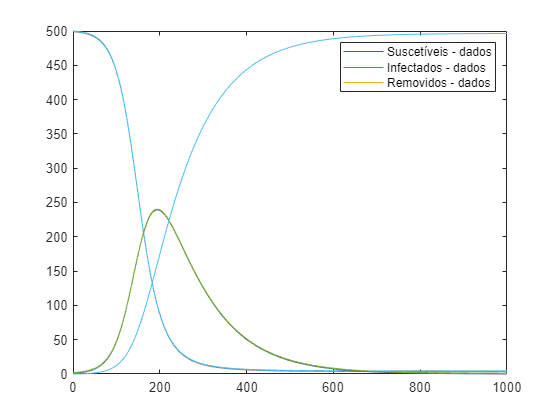

t = linspace(0,length(Sd),length(Sd));

figure(1)
plot(t,Sd)
hold on
plot(t,Id)
plot(t,Rd)
legend('Suscetíveis - dados','Infectados - dados','Removidos - dados')
hold off

Condições Iniciais

% Tamanho da populção - N
N = 500;

% Valores iniciais 
I0 = 1 ;
R0 = 0;
S0 = N - I0;

% Vetor de condições iniciais

y0 = [S0 I0 R0];

% Beta -  taxa de contato,
% r - taxa média de recuperação (in 1/dia).

theta0 = [1e-4,1e-2]; % valores iniciais
beta = theta0(1);
r = theta0(2);

Estimativa de parâmetros

mdl = 'CovidEmBlocos';
load_system(mdl)
cs = getActiveConfigSet(mdl);
mdl_cs = cs.copy;
set_param(mdl_cs,'AbsTol','1e-5','SaveState','on','StateSaveName','xoutNew','SaveOutput','on','OutputSaveName','youtNew')
simOut = sim(mdl, mdl_cs);

Obtendo

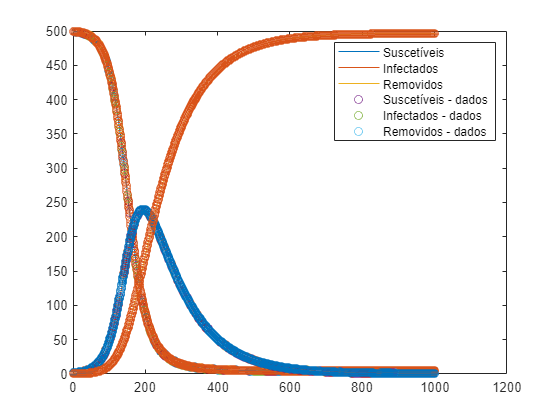

S = simOut.logsout{1}.Values.Data;
I = simOut.logsout{2}.Values.Data;
R = simOut.logsout{3}.Values.Data;

% Definição do conjunto de equações diferencias não lineares que formam o modelo.
t2 = linspace(0,length(S),length(S));

figure(2)

plot(t2, S)
hold on
plot(t2, I)
plot(t2, R)
scatter(t, Sd)
scatter(t, Id)
scatter(t, Rd)
legend('Suscetíveis','Infectados','Removidos','Suscetíveis - dados','Infectados - dados','Removidos - dados')
hold off